# LAB 09 Calculate and plot torque-speed characteristics of the Induction Motor for the following rotor resistance RR:

## (A) Chosen value of RR.

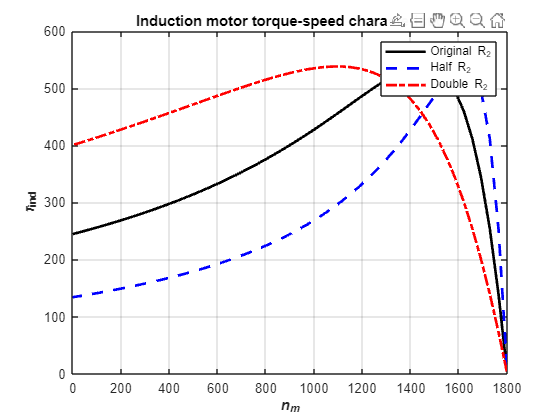

% Define motor parameters
rl = 0.641;         % Stator resistance (ohms)
xl = 1.106;         % Stator reactance (ohms)
r2 = 0.332;         % Rotor resistance (ohms)
x2 = 0.464;         % Rotor reactance (ohms)
xm = 26.3;          % Magnetizing reactance (ohms)
v_phase = 460 / sqrt(3);  % Phase voltage (volts)

% Define synchronous motor parameters
n_sync = 1800;      % Synchronous speed (RPM)
w_sync = 188.5;     % Synchronous angular velocity (rad/s)

% Calculate Thevenin equivalent voltage
v_th = v_phase * (xm /sqrt(rl^2 * (xl + xm)^2));

% Calculate Thevenin equivalent impedance
z_th = ((j*xm)*(rl + j*xl) / (r1 + (j*(x1 + xm)))); % Note: r1 and x1 are undefined

% Extract real and imaginary parts of Thevenin impedance
r_th = real(z_th);
x_th = imag(z_th);

% Define slip values and calculate corresponding motor speeds
s = (0:1:50)/50;
s(1) = 0.001;
nm = (1 - s) * n_sync;

% Preallocate arrays for torque values
t_ind1 = zeros(1, numel(s));
t_ind2 = zeros(1, numel(s));
t_ind3 = zeros(1, numel(s));

% Calculate torque for original rotor resistance scenario
for ii = 1:51
    t_ind1(ii) = (3 * v_th^2 * r2 / s(ii)) / ...
                 (w_sync * ((r_th + r2/s(ii))^2 + (x_th + x2)^2));
end

% Calculate torque for half the rotor resistance scenario
for ii = 1:51
    t_ind2(ii) = (3 * v_th^2 * (r2/2) / s(ii)) / ...
                 (w_sync * ((r_th + (r2/2)/s(ii))^2 + (x_th + x2)^2));
end

% Calculate torque for double the rotor resistance scenario
for ii = 1:51
    % Double the value of rotor resistance
    t_ind3(ii) = (3 * v_th^2 * (2*r2) / s(ii)) / ...
                 (w_sync * ((r_th + (2*r2)/s(ii))^2 + (x_th + x2)^2));
end

% Plot torque-speed characteristics
plot(nm, t_ind1, 'Color', 'k', 'LineWidth', 2.0);
hold on;
plot(nm, t_ind2, 'Color', 'b', 'LineWidth', 2.0, 'LineStyle', '--');
plot(nm, t_ind3, 'Color', 'r', 'LineWidth', 2.0, 'LineStyle', '-.');
xlabel('\itn_{m}', 'FontWeight', 'Bold');
ylabel('\tau_{ind}', 'FontWeight', 'Bold');
title('Induction motor torque-speed characteristic', 'FontWeight', 'Bold');
legend('Original R_{2}', 'Half R_{2}', 'Double R_{2}');
grid on;
hold off;